# Identifying a 4D SSM for an oscillator chain

This is an example of how to reconstruct the slow 4D SSM of a mechanical system using synthetic measurements of the full state space. In this example, we consider a damped oscillator chain with an additional nonlinear spring attached to the leftmost mass. The measurements for this example are transients occurring from exact initial conditions on the slow 4D SSM.

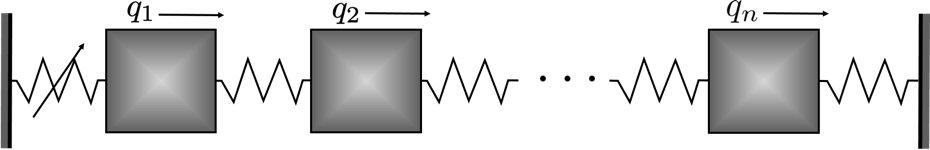

clearvars
close all

## Example setup

The $N$-degree of freedom dynamical system is of the form


$$\mathbf{M\ddot{q}} + \mathbf{C\dot{q}} + \mathbf{Kq} + \mathbf{f}(\mathbf{q},\mathbf{\dot{q}}) 
= \mathbf{0}$$


where $\mathbf{f}=\mathcal{O}(|\mathbf{q}|^2,|\mathbf{\dot{q}}|^2,|\mathbf{q}||\mathbf{\dot{q}}|)$ represents the nonlinearities and $\mathbf{M}$, $\mathbf{C}$, and $\mathbf{K}$ are the $n\times m$ mass, stiffness, and damping matrices, respectively.

We rewrite the system in first-order form as


$$\mathbf{\dot{y}} = \mathbf{A}\mathbf{y} + \mathbf{G}(\mathbf{y}) = \mathbf{F}(\mathbf{y})$$


with

$\mathbf{y}=\left[\begin{array}{c}\mathbf{q}\\\dot{\mathbf{q}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}\mathbf{0}  & \mathbf{I}\\-\mathbf{M}^{-1}\mathbf{K} & -\mathbf{M}^{-1}\mathbf{C} \end{array}\right],\quad\mathbf{G}(\mathbf{y})=\left[\begin{array}{c}  \mathbf{0} \\ -\mathbf{M}^{-1}\mathbf{f}(\mathbf{y})\end{array}\right]$.

n         = 5;      % number of masses
mass      = 1;
mass1     = 1.5;
stiffness = 1;
dampingM   = 0.002;
dampingK   = 0.005;

vMass = ones(1,n);%fliplr(linspace(0.5,1,n)); %
M = mass*diag(vMass); M(1,1) = mass1;
K = stiffness*(2*eye(n) - diag(ones(1,n-1),-1) - diag(ones(1,n-1),1));
K(end,end) = 1;
C = dampingM*M + dampingK*K;

% nonlinearities: f1 = 0.33*q1dot^2 + 3*q1^3 + 0.7*q1^2*q1dot + 0.5*q1dot^3
F2 = sptensor(zeros(n, 2*n, 2*n)); F3 = sptensor(zeros(n, 2*n, 2*n, 2*n));
F2(1,n+1,n+1) = 0.33;    % q1dot^2
F3(1,1,1,1) = 3;         % q1^3
F3(1,1,1,n+1) = 0.7;     % q1^2*q1dot 
F3(1,n+1,n+1,n+1) = 0.5; % q1dot^3
fnl = {F2*mass1, F3*mass1};

[F, lambda, E] = functionFromTensors(M, C, K, fnl);

## Generation of Synthetic Data

Having set up the dynamics of the problem, we now move on to generate synthetic data, which will be used to fit a parametrisation of the manifold. We will divide the data into a training set, for model fitting, and a test set, for validation.

nTraj = 6;
indTest = [1];
indTrain = setdiff(1:nTraj, indTest);

We now set the initial conditions for the trajectories, which are picked exactly on the slow 4D SSM of the systems, computed using SSMTool.

ICRadius = 0.3;
IC = getSSMIC(M, C, K, fnl, nTraj, ICRadius, 4, 1);

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 4.245669e-03
modal damping ratio for 2 mode is 3.236388e-03
modal damping ratio for 3 mode is 3.848172e-03
modal damping ratio for 4 mode is 4.639624e-03
modal damping ratio for 5 mode is 5.267721e-03

 The first 10 eigenvalues are given as 
  -0.0012 + 0.2825i
  -0.0012 - 0.2825i
  -0.0025 + 0.7850i
  -0.0025 - 0.7850i
  -0.0046 + 1.2082i
  -0.0046 - 1.2082i
  -0.0075 + 1.6069i
  -0.0075 - 1.6069i
  -0.0100 + 1.8961i
  -0.0100 - 1.8961i

(near) outer resonance detected for the following combination of master eigenvalues
     0     4     3     0
     7     0     0     1
     4     0     0     3
     0     7     1     0
     3     0     1     0
     3     0     2     1
     4     1     1     0
     3     0     3     2
     4     1     

The data is generated by time-integration of the right-hand side of the system. In this case we are observing the full state space, so the `observable` function is the identity.

observable = @(x) x;
slowTime = 2*pi/abs(lambda(1));
nPeriods = 140; 
nDataPerPeriod = 50*2;
endTime = nPeriods * slowTime;
nSamp = nDataPerPeriod * nPeriods + 1;
dt = endTime/(nSamp-1);
tic
yData = integrateTrajectories(F, endTime, IC, nSamp, observable);

simulating trajectory 1 of 6...
simulating trajectory 2 of 6...
simulating trajectory 3 of 6...
simulating trajectory 4 of 6...
simulating trajectory 5 of 6...
simulating trajectory 6 of 6...


toc

Elapsed time is 3.346892 seconds.


## Plot generated trajectory data

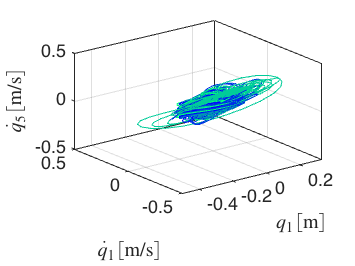

customFigure(); colororder(winter(nTraj));
for iTraj = 1:size(yData,1)
    plot3(yData{iTraj,2}(1,:), yData{iTraj,2}(n+1,:), yData{iTraj,2}(2*n,:),'Linewidth',1,'Displayname',['Trajectory ' num2str(iTraj)])
end
xlabel('$q_1 \, [$m$]$','Interpreter','latex'); 
ylabel('$\dot{q}_1 \, [$m/s$]$','Interpreter','latex'); 
zlabel(['$\dot{q}_{' num2str(n) '} \, [$m/s$]$'],'Interpreter','latex'); 
view(3)

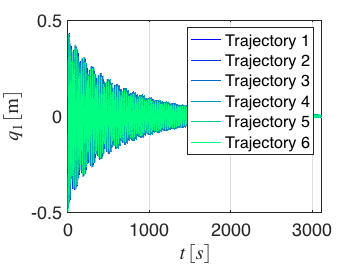



customFigure(); colororder(winter(nTraj));
for iTraj = 1:size(yData,1)
    plot(yData{iTraj,1}, yData{iTraj,2}(n,:),'Linewidth',1,'Displayname',['Trajectory ' num2str(iTraj)])
end
xlim([0 endTime])
xlabel('$t \, [s]$','Interpreter','latex'); 
ylabel('$q_1 \, [$m$]$','Interpreter','latex'); 
legend('location','NE')

## Datadriven manifold fitting

The measured trajectories are assumed to lie very close to a four-dimensional manifold that is tangent at the origin to the eigenspace corresponding to the two slowest pair of eigenvalues. We now want to fit a polynomial of order $M$ to the data points to approximate the manifold. Here we use a graph style parametrization, meaning that the manifold is parametrized using coordinates in the computed eigenspace $V_e$. This excludes the possibility of folds on the manifold (however, if necessary we may circumvent this problem by increasing the dimensionality of the observed space). 

We seek the $2n\times m_M$ polynomial coefficient matrix $H$ of the manifold on the form

$y = V_e V_e^\top y + H \phi_{m,2:M}(V_e^\top y) $,

where the function $\phi_{m,2:M}(q)$ computes a vector of all $m_M$ monomials from orders 2 up to $M$ of an $m$-vector $q$. This optimization problem amounts to minimizing a cost function computed from the measured data $y_k$,


$$C_r(V_e,H) = \sum_{k=1}^N ||y_k - V_eV_e^\top y_k - H\phi_{m,2:M}(V_e^\top 
y_k) ||$$


to find $H$ and the $2n\times 2$ eigenspace matrix $V_e$, under the constraints that $V_e^\top H=0$ and $V_e^\top V_e = I$. The minimization is performed with the Matlab routine `fmincon` in `IMGeometry`. Since we know the exact eigenspace, we set this as input to the code.

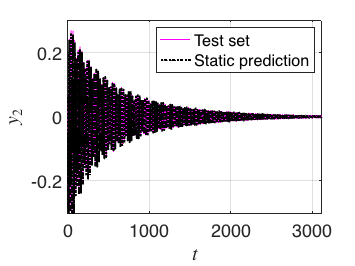

SSMOrder = 3; SSMDim = 4;
[IMInfo, SSMChart, SSMFunction] = IMGeometry(yData(indTrain,:), SSMDim, SSMOrder,'V_e',[real(E(:,1)) imag(E(:,1)) real(E(:,2)) imag(E(:,2))]);

% Get reduced-order coordinates
etaData = projectTrajectories(IMInfo, yData);

% Plot static reconstruction
yStaticRec = yData(indTest,:);
yStaticRec {1,2} = IMInfo.parametrization.map(etaData{indTest,2});
plotTrajectories(yData(indTest,:), yStaticRec, 'm', fix(n/2), {'Test set', 'Static prediction'})

## Reduced order model

We compute a model for the reduced dynamics with the truncated training data projected onto the manifold. The function `IMDynamicsFlow` fits a polynomial map


$$\dot{\eta} = R(\eta) = W_r \phi(\eta)$$


where $\phi(\eta)$ again computes a vector of all monomials of $\eta$, and  $W_r$ is a matrix of polynomial coefficients. 

We are also specifying that we want the reduced dynamics in normal form, so that the map $N$ will fulfill


$$\dot{z} = N(z) = Dz + W_n\phi(z)$$


with $D$ a diagonal matrix and $W_n$ coefficients for the near-resonant nonlinear terms, after a near-identity change of coordinates


$$z = T^{-1}(\eta) = \eta + W_t \phi(\eta)$$


with $W_t$ containing the coefficients for the nonlinear terms of the coordinate change.

If we know $D$ from the model, we can enforce it in the data-driven dynamics identification. To do so, we fix the linear part of $R$. These dynamics act on coordinates being orthogonal projections on the eigenspace, which are not modal coordinates where the linear part of the dynamics is indeed the diagonal matrix $D$. However, these two coordinate systems are linked by a linear transformation. More precisely, we define

$P = V_e^\top E$ ,

where the columns of $E$ are the eigenvectors related to the SSM. So, we then have 

$DR(0) = P D P^{-1}$ .

We expect the polar normal form of the dynamics for this 4D nonresonant SSM case to take the form

$\dot{\rho}_1 = c_1(\rho_1,\rho_2)\rho_1 $ ,

$\dot{\rho}_2 =  c_2(\rho_1,\rho_2)\rho_2 $ ,

$\dot{\theta}_1 =  \omega_1(\rho_1,\rho_2)$ ,

$\dot{\theta}_2 =  \omega_2(\rho_1,\rho_2)$ ,

which is identified from data using the function `IMDynamicsFlow`. In case of internal resonance, the polar vector field above also shows dependence on phases.

P = transpose(IMInfo.parametrization.tangentSpaceAtOrigin)*[E(:,1) E(:,2) E(:,1+n) E(:,2+n)];
DR0 = (P * diag(lambda([1 2 1+n 2+n])) ) / P ;
ROMOrder = 3; % Order for the normal form dynamics
RDInfo = IMDynamicsFlow(etaData(indTrain,:), 'R_PolyOrd', 1, 'N_PolyOrd', ROMOrder, 'style', 'modal');

Estimation of the reduced dynamics...  Done. 


We transform the truncated initial condition of our test trajectory according to the obtained change of coordinates, and integrate our reduced order evolution rule to predict the development of the trajectory.

[yRec, etaRec, zRec] = advect(IMInfo, RDInfo, yData);

## Evaluation of reduced dynamics

The error RRMSE is computed as the average distance of the predicted trajectory to the measured one in the full state space. We also plot the testing trajectory

normedTrajDist = computeTrajectoryErrors(yRec, yData);
RRMSE = mean(normedTrajDist(indTest))

RRMSE = 0.0265

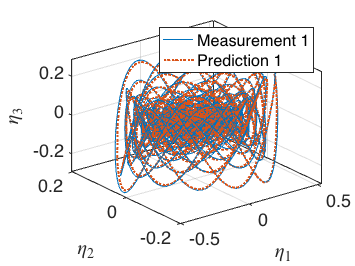


% Plot reduced coordinates
plotReducedCoordinates(etaData(indTest,:), etaRec(indTest,:))
view(3)

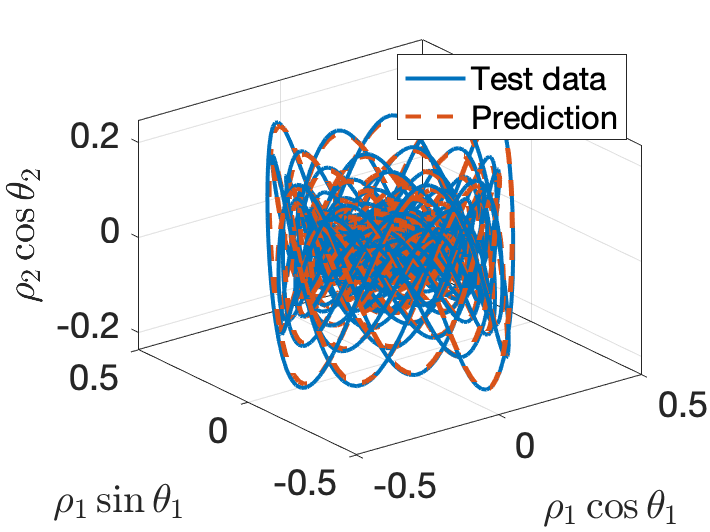

customFigure();

% Plot normal form coordinates
T_1 = RDInfo.inverseTransformation.map;
zDataTest = T_1(etaData{indTest,2});
zRecTest = zRec{indTest,2};
plot3(real(zDataTest(1,:)),imag(zDataTest(1,:)),real(zDataTest(2,:)),'Linewidth',2)
plot3(real(zRecTest(1,:)),imag(zRecTest(1,:)),real(zRecTest(2,:)),'--','Linewidth',2)
xlabel('$\rho_1\cos\theta_1$','Interpreter','latex')
ylabel('$\rho_1\sin\theta_1$','Interpreter','latex')
zlabel('$\rho_2\cos\theta_2$','Interpreter','latex')
legend('Test data','Prediction')
view(3)

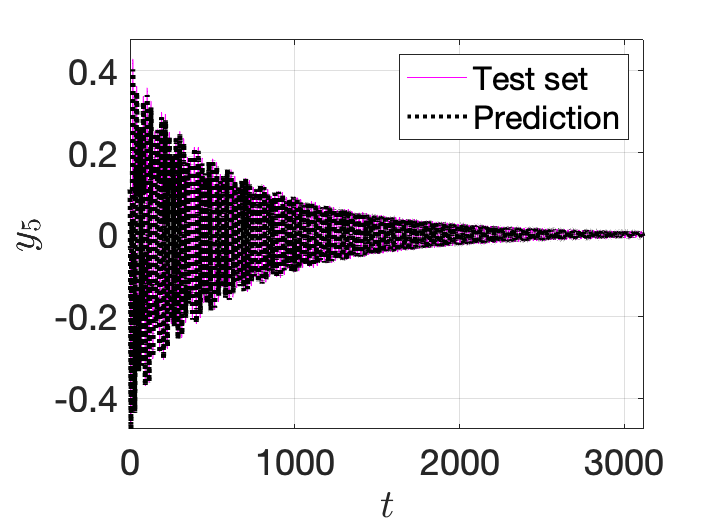


% Plot physical coordinates
plotTrajectories(yData(indTest,:), yRec(indTest,:), 'm', n, {'Test set', 'Prediction'})

## Backbone curves and frequency responses

We can now study the reduced order model. We extract backbones curves and forced response curves (FRCs). For the latter, our 

$$\dot{z} =N(z) + f_{red} e^{i\Omega t}$,

where $$\Omega$ is the forcing frequency and $$f_{red}$ is the forcing amplitude vector. For FRC extraction, we use the numerical continuation core coco. In this multimodal case, the backbone curves are those of the uncoupled oscillator limit, i.e., the backbones curves of a certain mode are computed setting to zero the amplitudes of the other modes.

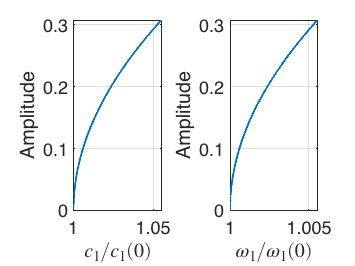

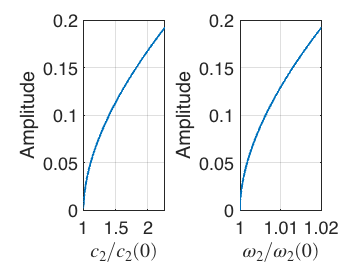

% Define the physical amplitude metric
reconstructedEigenvalues = RDInfo.eigenvaluesLinPartFlow; ndofSSM = SSMDim/2; 
amplitudeFunction = @(x) x(n,:); maxRho = max(abs(zRec{1,2}(1:2,:)),[],2);

% Compute backbone curves in the training range of data
BBCInfo = backboneCurves(IMInfo, RDInfo, amplitudeFunction,maxRho, 'norm');

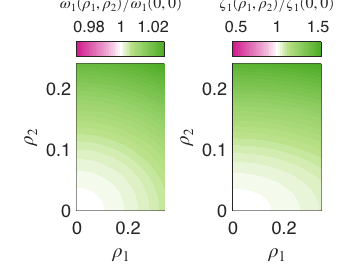

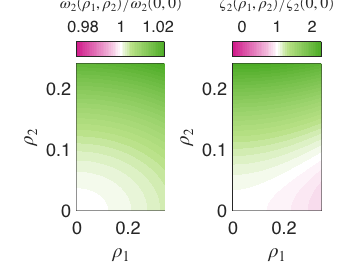

BBSInfo = backboneSurfaces(RDInfo, maxRho, 'norm');

% Compute frequency response curves
omegaSpan = [0.95 1.05].*transpose(abs(reconstructedEigenvalues(1:ndofSSM))); 
forcingSpan = [1 2.5 5; [.5 1.25 2.5]*3]*1e-4; % Assumes forcings on different dofs to have the same phase
[IMInfoF,RDInfoF] = forcedSSMROM(IMInfo,RDInfo,'nForcingFrequencies',1);

Forced SSM reduced-order model assumes external forcing only along the tangent (modal) subspace at the origin. 


FRCDataCOCO = continuationFRCpo(IMInfoF,RDInfoF,forcingSpan,omegaSpan,amplitudeFunction);

Frequency sweep for the set of forcing values number 1 ...

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.48e-04  4.68e+01    0.0    0.0    0.0
   1   1  1.00e+00  1.05e-04  7.41e-13  4.68e+01    0.0    0.0    0.0
   2   1  1.00e+00  3.61e-11  1.58e-17  4.68e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE     po.period            T
    0  00:00:00   4.6817e+01      1  EP      2.3409e+01   2.3409e+01
   10  00:00:01   4.4736e+01      2          2.2367e+01   2.2367e+01
   20  00:00:02   4.4568e+01      3          2.2283e+01   2.2283e+01
   30  00:00:03   4.4473e+01      4          2.2235e+01   2.2235e+01
   40  00:00:03   4.4388e+01      5          2.2193e+01   2.2193e+01
   50  00:00:04   4.4267e+01      6          2.2133e+01   2.2133e+01
   60  00:00:05   4.3971e+01      7          2.1986e+01   2.1986e+01
   70  00:00:05   4.0637e+01      8  

Unrecognized function or variable 'phase'.

Error in continuationFRCpo (line 115)
        uPhase(ind) = phase( normTimeEval(2) * sum( yAmplitudeFunction.*(cPhi-1i*sPhi ) ));


freqNorm = BBCInfo.frequency(1,1);
% Plot backbone curves and FRCs
customFigure('subPlot',[1 ndofSSM]); colors = colororder;
for idof = 1:ndofSSM
    subplot(1,ndofSSM,idof)
    plot(BBCInfo.frequency(idof,:)/freqNorm, BBCInfo.amplitude(idof,:),'k',...
        'Linewidth',1,'DisplayName', 'Backbones')
    plotFRC(FRCDataCOCO, colors(1,:),', 4DSSM','freqscale',freqNorm)
    ylim([0 max(max(BBCInfo.amplitude))])
    xlim([0.96 1.04].*transpose(abs(reconstructedEigenvalues(idof)))/freqNorm); 
    legend('off')
    xlabel('$\Omega/\omega(0)$','Interpreter','latex'); 
    ylabel('$q_5 \, [$m$]$','Interpreter','latex');
end
legend('location','north')